# Wiener


$$\mathit{\mathbf{y}}=\left\lbrack \begin{array}{c}
y\left\lbrack n\right\rbrack \\
y\left\lbrack n-1\right\rbrack 
\end{array}\right\rbrack$$



$${\mathit{\mathbf{R}}}_{\mathit{\mathbf{y}}} =\left\lbrack \begin{array}{cc}
E\left\lbrace y^2 \left\lbrack n\right\rbrack \right\rbrace  & E\left\lbrace y\left\lbrack n\right\rbrack y\left\lbrack n-1\right\rbrack \right\rbrace \\
E\left\lbrace y\left\lbrack n-1\right\rbrack y\left\lbrack n\right\rbrack \right\rbrace  & E\left\lbrace y^2 \left\lbrack n-1\right\rbrack \right\rbrace 
\end{array}\right\rbrack$$



$$=\left\lbrack \begin{array}{cc}
3\ldotp 56 & 1\ldotp 6\\
1\ldotp 6 & 3\ldotp 56
\end{array}\right\rbrack$$



$$Y\left(z\right)=X\left(z\right)H\left(z\right)=X\left(z\right)+1\ldotp 6z^{-1} X\left(z\right)$$



$$H\left(z\right)=1+1,6z^{-1}$$



$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +1,6x\left\lbrack n-1\right\rbrack$$



$${\mathit{\mathbf{R}}}_{\textrm{xy}} =E\left\lbrace \mathit{\mathbf{y}}\;x\left\lbrack n\right\rbrack \right\rbrace =\left\lbrack \begin{array}{c}
E\left\lbrace y\left\lbrack n\right\rbrack x\left\lbrack n\right\rbrack \right\rbrace \\
E\left\lbrace y\left\lbrack n-1\right\rbrack x\left\lbrack n\right\rbrack \right\rbrace 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$$



$$\mathit{\mathbf{w}}={{\mathit{\mathbf{R}}}_{\mathit{\mathbf{y}}} }^{-1} {\mathit{\mathbf{R}}}_{\textrm{xy}} =\left\lbrack \begin{array}{c}
0,352\\
-0,1582
\end{array}\right\rbrack$$


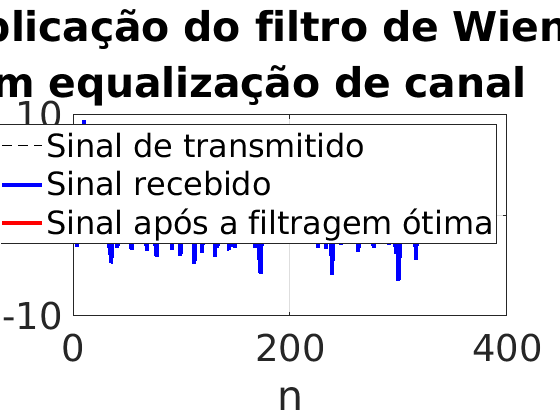

Ry = [3.56 1.6 ; 1.6 3.56];
Rxy = [1;0];
wo = Ry\Rxy;
L = 330;
Llms = L;
n=1:L;
x = wgn(1,L,1);
num = [1 1.6];
dem = 1;
% H = filt([1 1.6],1);
y = filter([1 1.6],1,x);
yo = filter([wo(1) wo(2)],1,y);
p = plot(n,x,n,y,n,yo);
p(1).LineStyle='--';
p(1).Color='black';
% p(1).LineWidth = 2;
p(2).LineWidth = 3;
p(2).Color='blue';
p(3).LineWidth = 3;
p(3).Color='red';

legend({'Sinal de transmitido', 'Sinal recebido', 'Sinal após a filtragem ótima'},'FontSize',24);
xlabel('n','FontSize',36)
title('Aplicação do filtro de Wiener \newline em equalização de canal', 'FontSize',40)
grid on
ax = gca;
ax.FontSize=28;

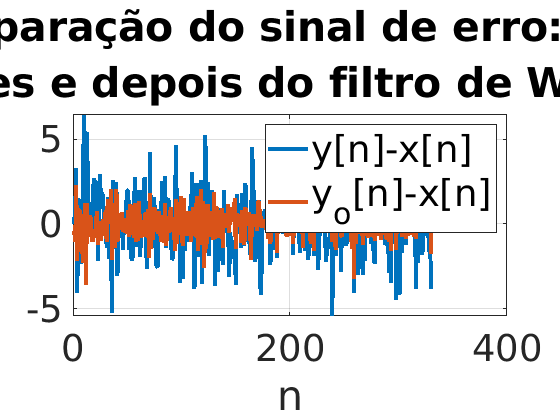

ey =  y - x;
eyo = yo- x;

p = plot(n,ey,n,eyo);
p(1).LineWidth = 3;
p(2).LineWidth = 3;
legend({'y[n]-x[n]', 'y_o[n]-x[n]'},'FontSize',28);
xlabel('n','FontSize',36)
title('Comparação do sinal de erro: \newline Antes e depois do filtro de Wiener', 'FontSize',40);
grid on
ax = gca;
ax.FontSize=28;


$$J\left(\mathit{\mathbf{w}}\right)=E\left\lbrack e^2 \left\lbrack n\right\rbrack \right\rbrack$$


# Algoritmo do gradiente

[Q, lambda] = eig(Ry)

Q =    -0.7071    0.7071
    0.7071    0.7071


lambda =     1.9600         0
         0    5.1600



$$Q=\left\lbrack \begin{array}{cc}
-0,7071 & 0,7071\\
0,7071 & 0,7071
\end{array}\right\rbrack$$



$$\Lambda =\left\lbrack \begin{array}{cc}
1,96 & 0\\
0 & 5,16
\end{array}\right\rbrack$$



$$\mathit{\mathbf{v}}\left\lbrack n\right\rbrack =\left\lbrack \begin{array}{c}
v_0 \left\lbrack n\right\rbrack \\
v_1 \left\lbrack n\right\rbrack 
\end{array}\right\rbrack ={\mathit{\mathbf{Q}}}^T {\mathit{\mathbf{w}}}_{\mathit{\mathbf{e}}}$$



$$\mathit{\mathbf{w}}\left\lbrack n\right\rbrack$$



$$\mathit{\mathbf{v}}\left\lbrack 0\right\rbrack =-{\mathit{\mathbf{Q}}}^T {\mathit{\mathbf{w}}}_o =\left\lbrack \begin{array}{c}
0,36\\
-0,137
\end{array}\right\rbrack$$


v0 = - Q.' * wo

v0 =     0.3608
   -0.1370



$$\mathit{\mathbf{v}}\left\lbrack n\right\rbrack ={\left(\mathit{\mathbf{I}}-2\mu \Lambda \right)}^n \mathit{\mathbf{v}}\left\lbrack 0\right\rbrack$$


mu = 0.05;
aux = eye(2)-2*mu*lambda

aux =     0.8040         0
         0    0.4840



$$\mathit{\mathbf{v}}\left\lbrack n\right\rbrack =\left\lbrack \begin{array}{c}
1,96\times 0,{804}^n \\
0
\end{array}\right\rbrack$$



$$\mathit{\mathbf{w}}\left\lbrack n\right\rbrack ={\mathit{\mathbf{w}}}_{\mathit{\mathbf{o}}} +\sum_{j=0}^1 {\mathit{\mathbf{q}}}_{\mathit{\mathbf{j}}} v_j \left\lbrack n\right\rbrack {\left(1-2\mu \lambda_j \right)}^n$$


autova = diag(lambda)

autova =     1.9600
    5.1600


wn = [wo(1) Q(1,1)*v0(1) (1-2*mu*autova(1)) Q(1,2)*v0(2) (1-2*mu*autova(2)); ...
    wo(2) Q(2,1)*v0(1) (1-2*mu*autova(1)) Q(2,2)*v0(2) (1-2*mu*autova(2))]

wn =     0.3520   -0.2551    0.8040   -0.0969    0.4840
   -0.1582    0.2551    0.8040   -0.0969    0.4840



$$\mathit{\mathbf{w}}\left\lbrack n\right\rbrack =\left\lbrack \begin{array}{c}
0,352-0,2551\times 0,{804}^n -0,0969\times 0,{484}^n \\
-0,1582+0,2551\times 0,{804}^n -0,0969\times 0,{484}^n 
\end{array}\right\rbrack$$


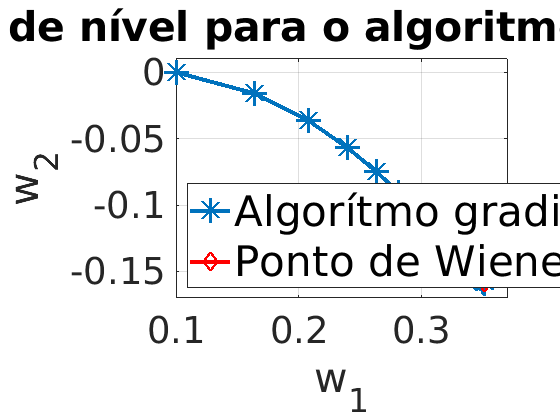

n = 1:100;
w1 =  0.352-0.2551*0.804.^n-0.0969*0.4840.^n;
w2 = -.1582+0.2551*0.804.^n-0.0969*0.4840.^n;
p = plot(w1,w2,wo(1),wo(2));
p(1).Marker= '*';
p(1).MarkerSize = 18;
p(1).LineWidth = 3;
p(2).Marker = 'diamond';
% p(2).MarkerFaceColor ='red';
p(2).MarkerSize = 10;
p(2).Color = 'red';
p(2).LineWidth = 3;

axis([0.1 .37 -.17 .01]);
legend({'Algorítmo gradiente','Ponto de Wiener'},'FontSize',32,'Location','southwest');
xlabel('w_1','FontSize',36)
ylabel('w_2','FontSize',36)
title('Curva de nível para o algoritmo gradiente', 'FontSize',40)
grid on
ax = gca;
ax.FontSize=28;
grid on

# Método de Newton    


$$\mathit{\mathbf{w}}\left\lbrack n+1\right\rbrack =\mathit{\mathbf{w}}\left\lbrack n\right\rbrack -\mu \left\lbrack \mathit{\mathbf{w}}\left\lbrack n\right\rbrack -{{\mathit{\mathbf{R}}}_{\mathit{\mathbf{y}}} }^{-1} {\mathit{\mathbf{R}}}_{\textrm{xy}} \right\rbrack$$


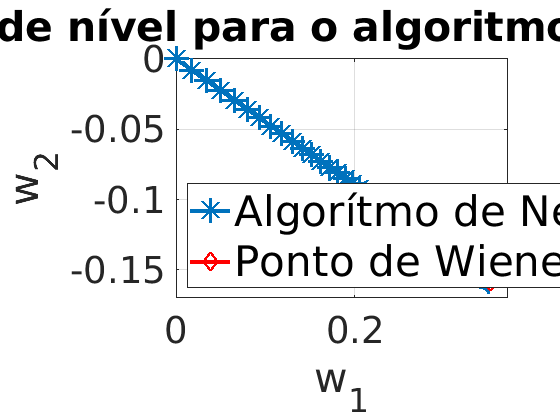

L = 100;
wnewton = zeros(2,L);

for i=1:L
    try
        wnewton(:,i) = wnewton(:,i-1)-mu*(wnewton(:,i-1)-wo);
    catch
    end
end
n = 1:L;
p = plot(wnewton(1,:),wnewton(2,:),wo(1),wo(2));
p(1).Marker= '*';
p(1).MarkerSize = 18;
p(1).LineWidth = 3;
p(2).Marker = 'diamond';
% p(2).MarkerFaceColor ='red';
p(2).MarkerSize = 10;
p(2).Color = 'red';
p(2).LineWidth = 3;

legend({'Algorítmo de Newton','Ponto de Wiener'},'FontSize',32,'Location','southwest');
xlabel('w_1','FontSize',36)
ylabel('w_2','FontSize',36)
title('Curva de nível para o algoritmo de Newton', 'FontSize',40)
grid on
ax = gca;
ax.FontSize=28;
axis([0 .37 -.17 0]);

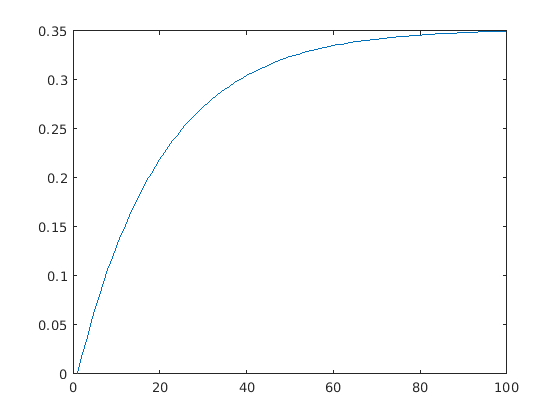

plot(n,wnewton(1,:))

# Método LMS


$$\mathit{\mathbf{w}}\left\lbrack n+1\right\rbrack =w\left\lbrack n\right\rbrack +2\mu \mathit{\mathbf{x}}\left\lbrack n\right\rbrack e\left\lbrack n\right\rbrack$$


L = Llms;
wLMS = zeros(2,L);
yoLMS = zeros(1,L);
eyoLMS= zeros(1,L);
mu = 0.00045

mu = 4.5000e-04

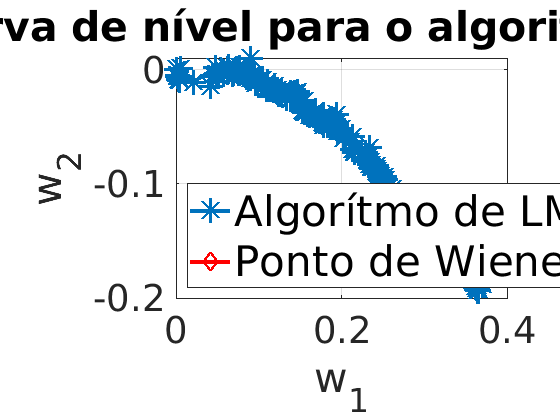

n = 1:L;
for i=1:L
    try
        yoLMS(i-1) =  wLMS(1,i-1)*y(i-2) + wLMS(2,i-1)*y(i-1);
        eyoLMS(i-1) = x(i-1)-yoLMS(i-1);
        wLMS(:,i) = wLMS(:,i-1)+2*mu*[y(i-1);y(i-2)]*eyoLMS(i-1);
    catch
    end
end
p = plot(wLMS(1,:),wLMS(2,:),wo(1),wo(2));

p(1).Marker= '*';
p(1).MarkerSize = 18;
p(1).LineWidth = 3;
p(2).Marker = 'diamond';
% p(2).MarkerFaceColor ='red';
p(2).MarkerSize = 10;
p(2).Color = 'red';
p(2).LineWidth = 3;

legend({'Algorítmo de LMS','Ponto de Wiener'},'FontSize',32,'Location','southwest');
xlabel('w_1','FontSize',36)
ylabel('w_2','FontSize',36)
title('Curva de nível para o algoritmo LMS', 'FontSize',40)
grid on
ax = gca;
ax.FontSize=28;